folder = fileparts(which('C:\Users\User\OneDrive\Documents\githubProjects\PE_Omission-Anat\eeglab2023.0\functions')); 
addpath(genpath(folder));

## Use of Anat's code to extract and preprocess orig data for Sleep Events (ss & kcomp) detection

******************************************************


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
EEGLAB warning: there can be only one EEGLAB window, closing old one
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.1 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


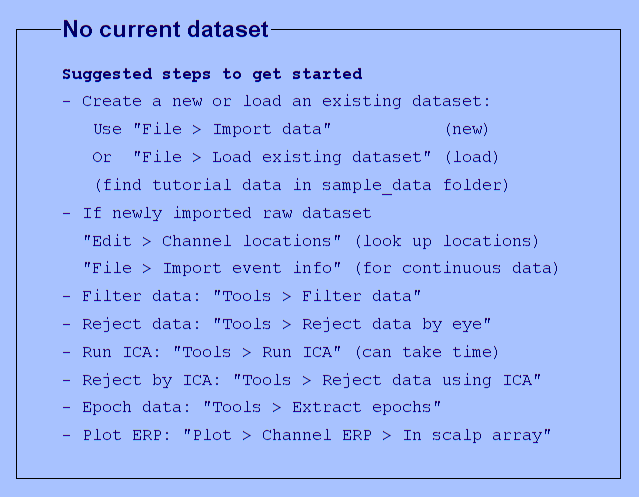

You are using the latest version of EEGLAB.


import_type ='eventDetectionChan';
preproc_name =  'imported';

input_dir = 'C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\';
output_dir = strcat('C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\eventDetection\',preproc_name,'_',import_type,'\');


electrodesNames =     { 'E9','E22','E36','E104','E70','E83','E24','E124','E52','E92','Cz'}; 
electrodesPSG_names = {'Fp1','Fp2','C3','C4','O1', 'O2','F3',  'F4', 'P3', 'P4', 'Cz'};

subs = {'08','09','10','12','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};
subs = {'32','38'};
[ALLEEG EEG CURRENTSET ALLCOM] = eeglab;

if ~isfolder(output_dir)
    mkdir(output_dir);
end

for sub_ind=1:size(subs,2)
    for sleepFileNum=1:6
        % run only if output file doesnt exists
        sleep_files_name_suffix = strcat('_sleep',num2str(sleepFileNum),'_',preproc_name,'.set');
        output_filename = strcat('sub',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_', preproc_name, '_',import_type);
        output_filename = output_filename{1};
        if isfile([output_dir output_filename '.mat'])
            string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  output_filename))
            continue
        end
        
        % upload .set file
        set_filename = strcat('s_',subs(sub_ind),'_sleep',num2str(sleepFileNum),'_orig.set');
        set_filename = set_filename{1};
        if ~isfile([input_dir '\' set_filename])
            ['no input file ' input_dir set_filename]
            continue
        end
        try
            EEG =  pop_loadset(set_filename, input_dir);
            [ALLEEG, EEG, CURRENTSET] = eeg_store( ALLEEG, EEG, 0 );
            EEG = eeg_checkset(EEG);
        catch ME
            ['error uploading ' input_dir set_filename]
            continue
        end 

        % reref to mastoid
        EEG = rereferenceFullNightSleep(EEG,3); %3 = linked mastoid
            
        % get labels and change thire names 
        all_labels = {EEG.chanlocs.labels};
        electrodesNumber =[];
        for label_ind=1:size(all_labels,2)
            if any(ismember(electrodesNames, all_labels(label_ind)))
                electrodesNumber(end+1) = label_ind;
            end
        end
        if size(electrodesNames,2) > size(electrodesNumber,2) 
            'didnt find all electrodes labels' 
        end
        [EEG.chanlocs(1,electrodesNumber).labels] = deal(electrodesPSG_names{:});
                    
        % exclude all electrode but the ones listed in loc
        chanexcl = 1:size(all_labels,2);
        chanexcl(electrodesNumber) = [];
        EEG = pop_select(EEG,'nochannel',chanexcl);
        
        % Bandpass filter EEG electrods
        lpfreq = 45;
        fprintf('Low-pass filtering above %dHz...\n',lpfreq);
        EEG45 = pop_eegfiltnew(EEG, [], lpfreq, 66, 0, [], 0);
        hpfreq = 0.35;% % (Anat's PSG was 0.5)
        fprintf('High-pass filtering EEG below %dHz...\n',hpfreq);
        EEG = pop_eegfiltnew(EEG45, [], hpfreq, 8500, true, [], 0);% EEG electrodes

        %% savings
        % save .set
        [ALLEEG EEG CURRENTSET] = pop_newset(ALLEEG, EEG, 1,'gui','off');
        EEG = pop_saveset(EEG, 'filename',[output_filename],'filepath',output_dir);
        % save .bdf
        pop_writeeeg(EEG, [output_dir output_filename '.bdf'],'TYPE','BDF'); %% no other intersting parameters.

        % save .mat
        subEvents = EEG.event;
        subData = EEG.data;
        samplefreq = EEG.srate;
        chansNames  = electrodesPSG_names;
        save([output_dir, output_filename '.mat'],"subEvents","subData","samplefreq",'chansNames');
    end
end

ans = "Sub_32 already exists in path:sub32_sleep1_imported_eventDetectionChan"

ans = "Sub_32 already exists in path:sub32_sleep2_imported_eventDetectionChan"

ans = "Sub_32 already exists in path:sub32_sleep3_imported_eventDetectionChan"

ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_32_sleep4_orig.set'

ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_32_sleep5_orig.set'

ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_32_sleep6_orig.set'

pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_38_sleep1_orig.set ...


Creating a new ALLEEG dataset 1


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 45Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 45 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 57.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 3.500000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.35 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.252941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 2


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-4.635485e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 1.044928e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 136 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_38_sleep2_orig.set ...


Creating a new ALLEEG dataset 3


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 45Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 45 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 57.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 3.500000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.35 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.252941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 4


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-4.530995e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 1.086268e-06 (due to roundoff in PhysMax/Min)
Warning SWRITE: 496 NaNs added to complete data block.


pop_loadset(): loading file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_38_sleep3_orig.set ...


Creating a new ALLEEG dataset 5


Referencing to E57E100.
Re-referencing data


Removing 116 channel(s)...


Low-pass filtering above 45Hz...


pop_eegfiltnew() - performing 67 point lowpass filtering.
pop_eegfiltnew() - transition band width: 25 Hz
pop_eegfiltnew() - passband edge(s): 45 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 57.5 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


High-pass filtering EEG below 3.500000e-01Hz...


pop_eegfiltnew() - performing 8501 point highpass filtering.
pop_eegfiltnew() - transition band width: 0.1941 Hz
pop_eegfiltnew() - passband edge(s): 0.35 Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): 0.252941176470588 Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Creating a new ALLEEG dataset 6


Saving dataset...


Recreating event channel
Unifying channel resolution, clipping at +-4.174841e+04 uV 
Warning SOPEN (EDF-Write): relative scaling error is 2.432727e-07 (due to roundoff in PhysMax/Min)
Warning SWRITE: 292 NaNs added to complete data block.


ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_38_sleep4_orig.set'

ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_38_sleep5_orig.set'

ans = 'no input file C:\Users\User\Cloud-Drive\BigFiles\AnatArzData\Data\imported\s_38_sleep6_orig.set'